# Wheel Turning Speed Analysis

In the experiment reported by [Steinmetz et al, 2019 in Nature](https://www.nature.com/articles/s41586-019-1787-x), the mice perform a discrimination task where that had to find out which stimuli (left vs right) has the higher contrast. And they report their  decision by steering a wheel such that the stimuli with the higher  contrast moves to the center screen.

**Analysis Goals**

In this notebook we will be analyzing the speed at which the mouse turned the wheel to report their decision.

## **Download Data**

data_url = "https://uni-bonn.sciebo.de/s/O4sNoXeXfvyjfLZ";
userpath(fullfile(fileparts(matlab.desktop.editor.getActiveFilename), "src"))
download_from_sciebo(data_url, "data/steinmetz_2016-12-14_Cori.parquet")

Done!

userpath(fullfile(fileparts(matlab.desktop.editor.getActiveFilename), "data"))


## Visualising Wheel Turning Speed

In this section we will plot the speed at which the mouse turned the  wheel in every trial. 

The experimental data contains the wheel speed over time, across all  trials. A positive turning speed means that the wheel is being moved to  the right, while a negative speed tells us the wheel is being moved to  the left. When the wheel is not being moved at all, the turning speed is zero. 

The wheel speed data is binned in bins of 10ms, meaning the difference in time between each datapoint is 10ms.

The data for this exercise is in the parquet format. Parquet is a tabular data storage format that is readable in any programming language. It offers fast loading, consumes minimal space thanks to compression and is self-describing.

Let's load in our parquet file

data = parquetread("data/steinmetz_2016-12-14_Cori.parquet" );

**Example Exercise**

Plot the wheel speed against time for trial 7 

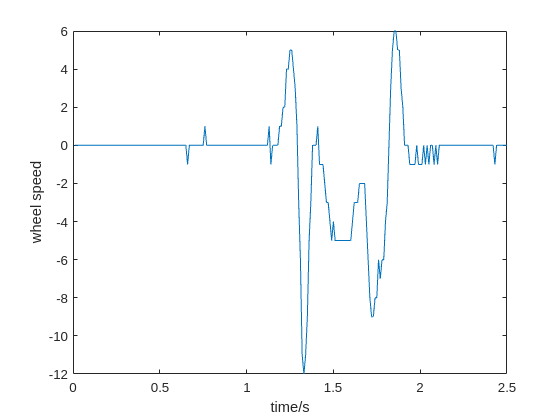

plot_data = data(data.trial==7,:);
plot(plot_data.time, plot_data.wheel_speed)

xlabel('time/s')
ylabel('wheel speed')

Plot the wheel speed against time for trial 99

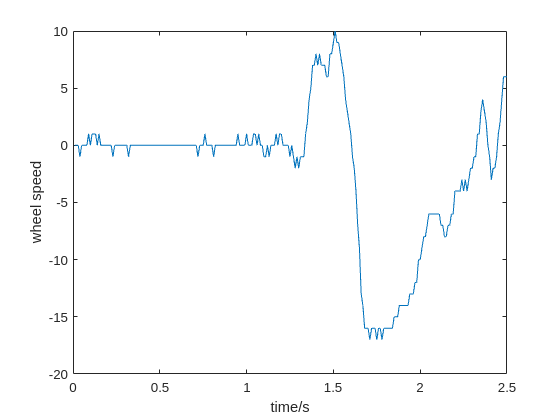

plot_data = data(data.trial==99,:);
plot(plot_data.time, plot_data.wheel_speed)

xlabel('time/s')
ylabel('wheel speed')

Plot the wheel speed against time for the last trial (ie. the largest trial number) in the data. There are many ways to do this!

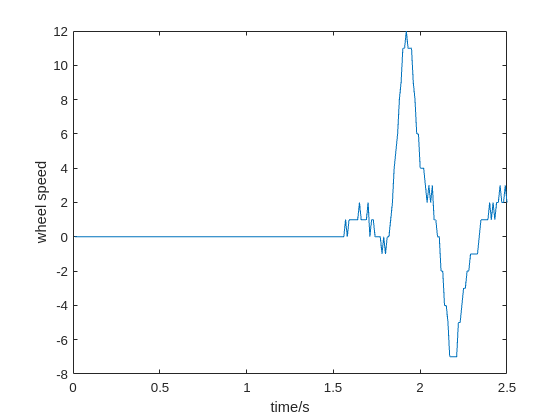

plot_data = data(data.trial==max(data.trial),:);
plot(plot_data.time, plot_data.wheel_speed)

xlabel('time/s')
ylabel('wheel speed')

Make a figure showing the wheel speeds of both trials 26 and 27. **Hint** - you will need to use the following pattern: 

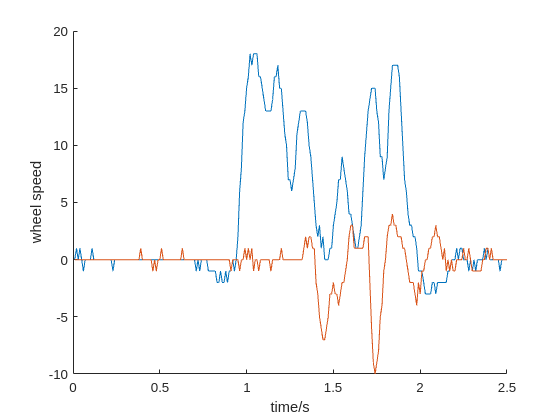

plot_data_t26 = data(data.trial==26,:);
plot_data_t27 = data(data.trial==27,:);

clf
hold on
plot(plot_data.time, plot_data_t26.wheel_speed)
plot(plot_data.time, plot_data_t27.wheel_speed)
hold off

xlabel('time/s')
ylabel('wheel speed')

Recreate the above plot adding legend labels to the lines

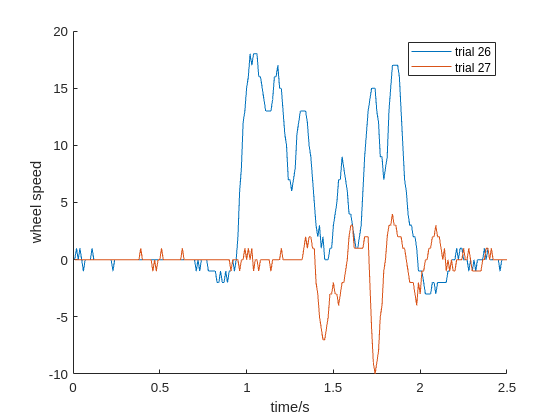

plot_data_t26 = data(data.trial==26,:);
plot_data_t27 = data(data.trial==27,:);

clf
hold on
plot(plot_data.time, plot_data_t26.wheel_speed,"DisplayName","trial 26")
plot(plot_data.time, plot_data_t27.wheel_speed,"DisplayName","trial 27")
hold off

xlabel('time/s')
ylabel('wheel speed')
legend()

Looks good! But the legend does obscure the data. Change the position of the legend. **Hint** run 

to view an explanation of possible options that can be given to` legend()`

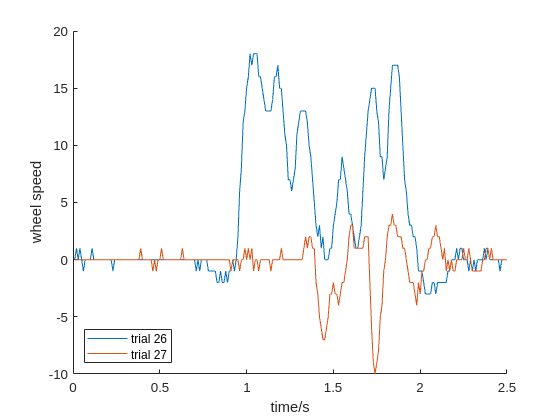

plot_data_t26 = data(data.trial==26,:);
plot_data_t27 = data(data.trial==27,:);

clf
hold on
plot(plot_data.time, plot_data_t26.wheel_speed,"DisplayName","trial 26")
plot(plot_data.time, plot_data_t27.wheel_speed,"DisplayName","trial 27")
hold off

xlabel('time/s')
ylabel('wheel speed')
legend("Location","southwest")

## Describing Data with Metrics: Determining Turning Direction

Data analysis is all about making sense of data. Statistics like  averages is one example of this. Such measures can help us minimise the  amount of data that we need to think about and allow to answer more  generic questions. In the context of the wheel speed data that we have  been working on so far, a natural question is: **which way did the subject turn the wheel?**

In this section, we will be using aggregation methods such as `mean()` combined with filtering to further analyze the wheel speed data for  instance to only look at trials in which the wheel was turned to the  left.

### Restructuring data

Before we start analysing the wheel speed, let's restructure our data such that it becomes a bit easier to analyse. Let's change the data table such that as rows we have `time` and as columns we have `trial. `This is known as a wide format

First, let's extract the wheel_speed data and reform it into a matrix with 250 columns, as each trial has 250 datapoints.

wheel_speed_data = data.wheel_speed;
wheel_speed = reshape(wheel_speed_data,250,214)'

wheel_speed = 214×250 single matrix
    -1     0     0     0     0     0     0     0     0     0     0     0     0     0    -1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0    -1     0     0     0     0     0     0     0     0    -1     0    -1     0
     0    -1     0    -1     0     1     0     1     1     1     0     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0    -1     0     0     1     0     0     1     0     0     0    -1     0     0     1     0     0     0     0     0     0    -1     0
     0     0    -1     0     0    -1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0    -1     0     0
     0     0     0     0     0     1     0     0     0     0 

From this maxtix we can make a table

wheel_speed_table= table(wheel_speed)

wheel_speed_table = 214×1 table
    wheel_speed 
    ____________

    1×250 single
    1×250 single
    1×250 single
    1×250 single
    1×250 single
    1×250 single
    1×250 single
    1×250 single
    1×250 single
    1×250 single
    1×250 single
    1×250 single
    1×250 single
    1×250 single
    1×250 single
    1×250 single


What is the size of the wheel speed data in the table?

size(wheel_speed_table.wheel_speed)

ans =    214   250


We have 214 trials and each trial has 250 datapoints of wheel speed, hence the size is 214x250. 

Say if we want to find the average wheel speed for each trial, we would then have 214 values

What is the size of the result `mean(data.wheel_speed)`?

size(mean(wheel_speed_table.wheel_speed))

ans =      1   250


By default MATLAB calculates the mean across the columns of the table. We are interested however in the mean across the rows. 

This is given by changing the axis across which the mean is calculated. By default the axis is 1, like this

mean(wheel_speed_table.wheel_speed,1)

ans = 1×250 single row vector
    0.1028    0.0701    0.0701    0.0280    0.0187    0.0187   -0.0234    0.0467    0.0047    0.0047   -0.0047   -0.0093   -0.0327    0.0374    0.0047   -0.0093    0.0093    0.0187         0   -0.0140    0.0280    0.0140   -0.0047    0.0047    0.0140         0   -0.0140   -0.0047   -0.0047    0.0093         0    0.0140   -0.0140   -0.0093    0.0140         0         0   -0.0093   -0.0093         0   -0.0140         0    0.0187   -0.0093    0.0140   -0.0047   -0.0093         0         0    0.0374


**Exercises**

Calculate the mean wheel speed for each trial. Name the result `mean_wheel_speeds`

mean_wheel_speeds = mean(wheel_speed_table.wheel_speed,2);

Make a new column in `wheel_speed_table` named "mean_wheel_speed" which holds the values of  `mean_wheel_speeds`

wheel_speed_table.mean_wheel_speed = mean_wheel_speeds;

In the next few steps, we will visualize the data for which the average wheel speed was greater that 0.

First, filter `data` for where the mean wheel speed is greater than 0. 

wheel_speed_table(wheel_speed_table.mean_wheel_speed>0,:)

ans = 116×2 table
    wheel_speed     mean_wheel_speed
    ____________    ________________

    1×250 single         4.376      
    1×250 single         2.616      
    1×250 single         2.532      
    1×250 single          0.94      
    1×250 single         0.336      
    1×250 single         4.276      
    1×250 single         2.892      
    1×250 single         5.132      
    1×250 single         3.732      
    1×250 single         2.932      
    1×250 single         1.556      
    1×250 single         1.052      
    1×250 single         4.056      
    1×250 single         3.652      
    1×250 single         4.128      
    1×250 single         0.336      


Find the wheel speeds where the mean wheel speed is greater than 0. Call this variable `mean_speed_gtr_zero. `We will judge that when the mean wheel speed is greater than 0, the wheel was turned to the right.

mean_speed_gtr_zero = wheel_speed_table{wheel_speed_table.mean_wheel_speed>0,"wheel_speed"};

**Example Exercise**

Plot the entire wheel speed data

plot(wheel_speed_table.wheel_speed')
xlabel('time bin')
ylabel('wheel speed')


Plot  the wheel speed data where the mean speed is greater than zero and compare to the plot above.

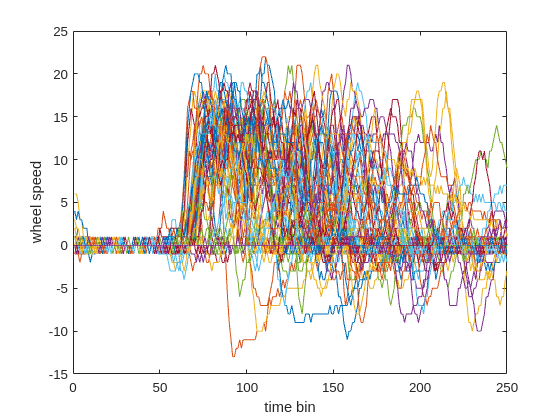

plot(mean_speed_gtr_zero')
xlabel('time bin')
ylabel('wheel speed')

Find the wheel speed data for when the mean speed was less than 0

mean_speed_less_zero = wheel_speed_table{wheel_speed_table.mean_wheel_speed<0,"wheel_speed"};

Plot the wheel speed against time for this data

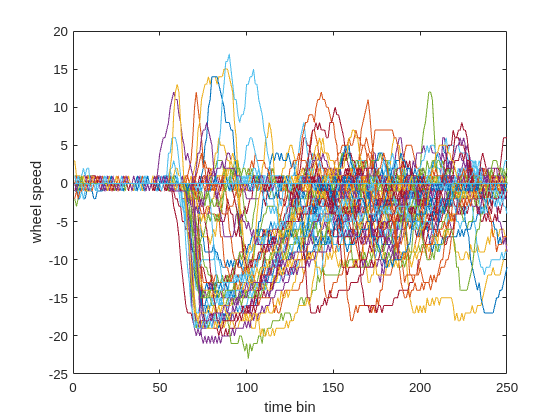

plot(mean_speed_less_zero')
xlabel('time bin')
ylabel('wheel speed')

We will not use a different criteria to determine the turning direction. Now we will say that whenever the maximum wheel turning speed was greater than 10, the wheel was turned to the right.

Calculate the maximum wheel turning speed of each trial. Remeber to take the maximum over the correct axis.

max(wheel_speed_table.wheel_speed,[],2 )

ans = 214×1 single column vector
    19
     5
    14
     7
    18
    14
     6
     6
     7
    20


Create a new column in `data `called `max_speed` which contains the maximum wheel turning speed for each trial

wheel_speed_table.max_speed = max(wheel_speed_table.wheel_speed,[],2);

Find the wheel speeds where the maximum wheel speed is greater than 10. Call this variable `max_speed_gtr_10 `

max_speed_gtr_10 = wheel_speed_table{wheel_speed_table.max_speed>10, "wheel_speed"};

Plot `max_speed_gtr_10` against `time_bins`

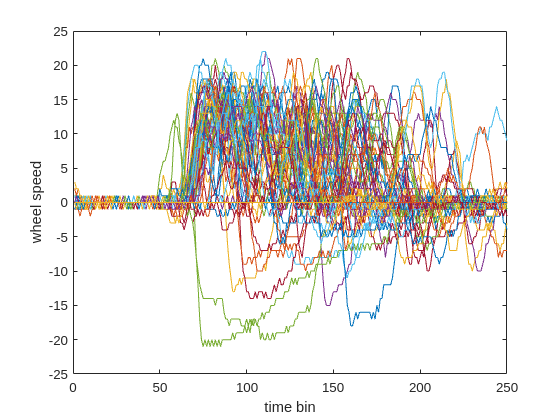

plot(max_speed_gtr_10')
xlabel('time bin')
ylabel('wheel speed')

## Result Validation Using Print Statements

In programming, print functions are integral for outputting  human-readable results. In this section we will use print statements to  compare different metrics to determine the wheel turning direction, and  produce cleanly formatted sentences

We have two metrics to determine the wheel turning direction:

- when the mean wheel speed is greater than 0 -> the wheel was turned to the right

- when the maximum turning speed is greater than 10 -> the wheel was turned to the right

Luckily, the dataset authors have also provided information in the dataset  that specifies when they considered the turn to be left, right, or no  turn. This information is in the `response_type` variable. 

A `response_type` of:

-  1  :  corresponds to a right turn

- −1:  corresponds to a left turn

-  0  :   corresponds to no turning at all

Let's compare our metrics for determining the turning direction with the information provided by the dataset authors.

**Example Exercise**

 Print the value of variable `var_a` using a format string.

var_a = 33;
fprintf("the value of var_a is %d",var_a)

the value of var_a is 33

**Exercises**

Print the number of trials where the mean speed is less than zero using a format string.

num_trials_mean_less_0 = height(wheel_speed_table(wheel_speed_table.mean_wheel_speed<0,:));
fprintf("The number of trials where the mean speed is less than zero is %d", num_trials_mean_less_0)

The number of trials where the mean speed is less than zero is 90

Print the number of trials where the mean speed is equal to zero.

num_trials_mean_eq_0 = height(wheel_speed_table(wheel_speed_table.mean_wheel_speed==0,:));
fprintf("%d trials had a mean speed of zero", num_trials_mean_eq_0)

8 trials had a mean speed of zero

Print the percentage of trials where the mean speed is equal to zero.

perc_value = 100* num_trials_mean_eq_0 /height(wheel_speed_table);
fprintf( "%d of percent trials had a mean speed of zero", perc_value)

3.738318e+00 of percent trials had a mean speed of zero

Are there too many decimal points in that number? We can apply rounding  to 4 decimal places by writing the print statement like so:

Display the percentage of trials with zero mean speed rounded to 3 decimal places.

fprintf( "%.3f percent of trials had a mean speed of zero", perc_value)

3.738 percent of trials had a mean speed of zero

Now let's move on to comparing the turning direction of our  predictions with those of the dataset authors, Steinmetz et. al. We will be focusing on the **right turns**.

Find the trial numbers of the table `data `where the response_type is 1. Call this `steinmetz_trials`.

steinmetz_trials = unique(data(data.response_type ==1,"trial"))

steinmetz_trials = 71×1 table
    trial
    _____

      1  
      3  
      5  
      6  
     10  
     11  
     13  
     14  
     15  
     22  
     23  
     25  
     26  
     29  
     34  
     40  


Use steinmetz_trials to index `wheel_speed_table` and find the `mean_wheel_speed` of trials when the wheel was turned to the right. Call this `mean_wheel_speed_right_trials`

mean_wheel_speed_right_trials= wheel_speed_table( steinmetz_trials.trial, "mean_wheel_speed")

mean_wheel_speed_right_trials = 71×1 table
    mean_wheel_speed
    ________________

         4.376      
         2.616      
         2.532      
          0.94      
         4.276      
         2.892      
         5.132      
         3.732      
         2.932      
         1.556      
         1.052      
         4.056      
         3.652      
         4.128      
         3.192      
         5.152      


Find the number of trials in wheel_speed_table where the mean wheel speed is greater than 0. Name this `n_right_turn_pos_mean_speed`.

n_right_turn_pos_mean_speed = height(mean_wheel_speed_right_trials(mean_wheel_speed_right_trials.mean_wheel_speed>0,:))

n_right_turn_pos_mean_speed = 67

Summarise the percentage of agreement between us and the dataset authors with a formattted print statement by comparing `n_right_turn_pos_mean_speed `with` steinmetz_trials`

perc_val = 100* n_right_turn_pos_mean_speed/height(steinmetz_trials);
fprintf("There is a %.2f percent agreement", perc_val)

There is a 94.37 percent agreement

Now we will make the same assessment but using the criteria that a right turn is made when the maximum wheel speed is greater than 10. 

Find the maximum wheel speeds of trials in `steinmetz_trials. `Call this `max_wheel_speed_right_trials`

max_wheel_speed_right_trials= wheel_speed_table( steinmetz_trials.trial, "max_speed")

max_wheel_speed_right_trials = 71×1 table
    max_speed
    _________

       19    
       14    
       18    
       14    
       20    
       17    
       17    
       21    
       15    
       16    
       14    
       20    
       18    
       17    
       17    
       19    


Find the number of rows where the max wheel speed is greater than 10 in `max_wheel_speed_right_trials`

n_right_turn_max_gtr_10 = height(max_wheel_speed_right_trials(max_wheel_speed_right_trials.max_speed>10,:))

n_right_turn_max_gtr_10 = 64

Summarise the agreement between this method and the dataset authors

perc_val = 100* n_right_turn_max_gtr_10/height(steinmetz_trials);
fprintf("There is a %.2f percent agreement", perc_val)

There is a 90.14 percent agreement

Which method do you think is more accurate for determining the turning direction, and why? 

## Demo: Visualising large datasets with a heatmap

Plotting large datasets comes with the risk of overplotting, for example:

data = parquetread("data/steinmetz_2016-12-14_Cori.parquet" );
wheel_speed_data = data.wheel_speed;
wheel_speed = reshape(wheel_speed_data,250,214)'

wheel_speed = 214×250 single matrix
    -1     0     0     0     0     0     0     0     0     0     0     0     0     0    -1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0    -1     0     0     0     0     0     0     0     0    -1     0    -1     0
     0    -1     0    -1     0     1     0     1     1     1     0     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0    -1     0     0     1     0     0     1     0     0     0    -1     0     0     1     0     0     0     0     0     0    -1     0
     0     0    -1     0     0    -1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0    -1     0     0
     0     0     0     0     0     1     0     0     0     0 

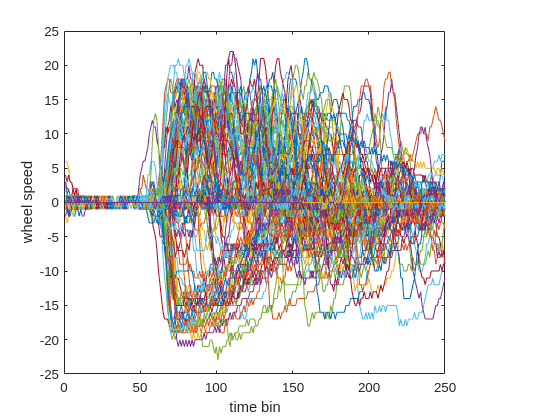

wheel_speed_table= table(wheel_speed);

plot(wheel_speed_table.wheel_speed')
xlabel('time bin')
ylabel('wheel speed')

We have a tangle of lines, and we can't really make much sense of the data. Another strategy is to plot a heatmap.

Here, we make a grid on the plot and count how many datapoints lie in each cell of the grid. This count is then displayed as a coloured value. 

Let's make a heatmap of the wheel speed data.

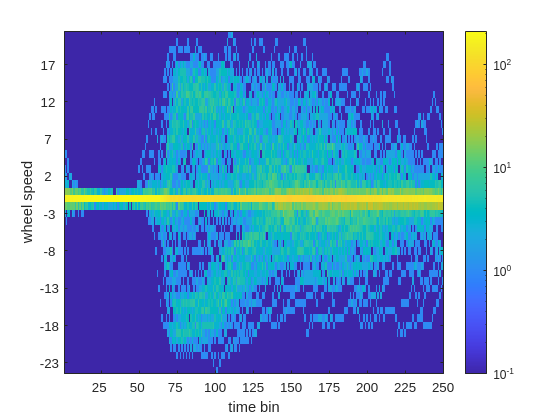

input_data = wheel_speed_table;

% define bin edges
yy =flip([min(input_data.wheel_speed,[],'all'):1:max(input_data.wheel_speed,[],'all')]');
ss =size(input_data.wheel_speed);

res =zeros([length(yy),ss(2)]); %matrix to store heatmap counts
 
% make counts
for i=1:ss(2)
    [n, edges]= histcounts(input_data.wheel_speed(:,i),[min(input_data.wheel_speed,[],'all'):max(input_data.wheel_speed,[],'all')+1]);
    res(:,i) = n';
end
res = flip(res);
 

im=image(res,'CDataMapping','scaled'); % draw matrix
colorbar % display colorbar
set(gca,'ColorScale','log') % set colorscale to log
 
 
% add axis tick labels
set(gca, 'XTick',[0:25:250], 'XTickLabel',[0:25:250])    
set(gca, 'YTick',[0:5:50], 'YTickLabel',flip([min(input_data.wheel_speed,[],'all'):5:max(input_data.wheel_speed,[],'all')]))    
% add axis labels
xlabel('time bin')
ylabel('wheel speed')

The heatmap reveals far more structure in the data that is not visible with the simple line plot. For example, that most of the time, the wheel speed is infact 0! 